# 21.1

1. 

syms u
assume(u,["positive","real"])
r = 4 * [0.3960*cos(2.65 * (u + 1.4)); -0.99 * sin(u + 1.4); 0 * u];
r = simplify(r);

$$r = \left(\begin{array}{c} \frac{198\,\cos\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{125}\\ -\frac{99\,\sin\left(u+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

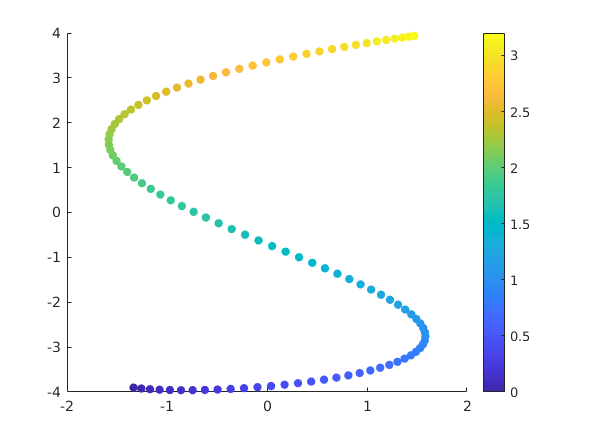

u_num = linspace(0, 3.2);
r_num = subs(r, u, u_num);
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar

2.

T_hat = simplify(diff(r,u)/norm(diff(r,u)));
N_hat = simplify(diff(T_hat,u)/norm(diff(T_hat,u)));
u_samples_indices = round(linspace(1, length(u_num), 5));
u_samples = u_num(u_samples_indices);
T_hat_samples = subs(T_hat, u, u_samples);
N_hat_samples = subs(N_hat, u, u_samples);

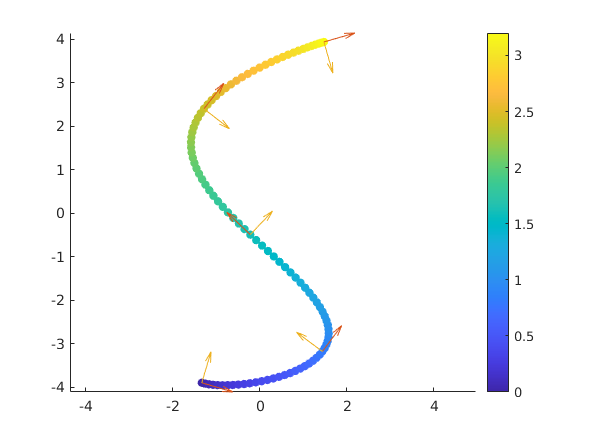

figure()
hold on
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), T_hat_samples(1,:), T_hat_samples(2,:), 0.2)
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), N_hat_samples(1,:), N_hat_samples(2,:), 0.2)
axis equal